**Transient Diffusion-Reaction Model for GDE-based Carbon Dioxide Electrolysis**

The following parameters may be altered to study its effect on the concentration profiles, pH, and explore the mass-transfer limiting current conditions:

T           =20 ; % temperature [degC]
P           =1 ; % pressure [bar]
j           =     -200  ; % current density [mA/cm2]
n_CO        =0.9; % CO Faradaic efficiency [-]
n_iHCOO     =0; % HCOO(-) Faradaic efficiency [-]
n_CH4       =0; % CH4 Faradaic efficiency [-]
n_C2H4      =0; % C2H4 Faradaic efficiency [-]
n_C2H5OH    =0; % C2H5OH Faradaic efficiency [-]
n_iCH3COO   =0; % CH3COO(-) Faradaic efficiency [-]
n           = [n_CO n_iHCOO n_CH4 n_C2H4 n_C2H5OH n_iCH3COO];

electrolyte = "KHCO3"      ;
c           =1000; % concentration of electrolyte [mM]
L           =320; % diffusion boundary layer length [um]

Specify a value for porosity *ε *and catalyst layer thickness *δ_*CL:

e           =0.5 ; % define porosity [-]
l           =0.5 ; % catalyst layer thickness [um]
k_m         = 0.03      ; % mass transfer coefficient [m/s]

Additional parameters for the numerical modelling algorithm:

n_xCL       = 21;       % number of grid points (must be odd-numbered)
n_xDBL      = 201;       % number of grid points (must be odd-numbered)
t           = 100;       % total time of simulation [s]
dt          = 10;       % time step size [s]

Hit the button below when settings are as desired:

***1D Transient Diffusion-Reaction Model for a Porous Electrode***


---PART I: Thermodynamic and Kinetic Parameters---

Thermodynamic state of the system:
	 T = 293.15 K
	 P = 1.00 bar
	 c = 1000.00 mol/m3 KHCO3
	 u = 1.14 mPa s (based on salt molarity and temperature)
	 p = 1061.1 kg/m3 (based on salt molarity)
Solubility of CO2 in equilibrium with 1.00 bar pure CO2 atmosphere:
	 37.9 mM (Henry Law)	 --->	 26.3 mM (Sechenov)
Diffusion coefficients of species in the catalyst layer (porosity- and tortuosity-corrected):
	 D(CO2)     = 5.200e-10 m2/s
	 D(NO3(-))  = 5.179e-10 m2/s
	 D(HCO3(-)) = 3.226e-10 m2/s
	 D(CO3(2-)) = 2.513e-10 m2/s
	 D(OH(-))   = 1.436e-09 m2/s
	 D(H(+))    = 2.535e-09 m2/s
	 D(NH4(+))  = 5.328e-10 m2/s
Diffusion coefficients of species in the diffusion layer:
	 D(CO2)     = 1.471e-09 m2/s
	 D(NO3(-))  = 1.465e-09 m2/s
	 D(HCO3(-)) = 9.126e-10 m2/s
	 D(CO3(2-)) = 7.108e-10 m2/s
	 D(OH(-))   = 4.061e-09 m2/s
	 D(H(+))    = 7.170e-09 m2/s
Corrected for temperature a

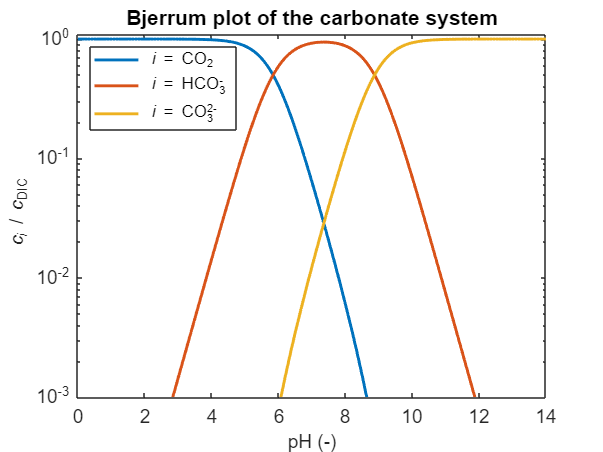


The fraction of CO2/HCO3(-)/CO3(2-) of the Dissolved Inorganic Content (DIC) as a function of pH.

The initial conditions of the electrolyte are:
	CO2     3.00000 mM
	OH(-)   0.00110 mM
	HCO3(-) 699.73407 mM
	CO3(2-) 150.13242 mM
	H(+)    0.00001 mM
	pH      8.21 

Elapsed time for PART II is 0.230 seconds.


---PART III: Concentration Profiles---

Model parameters:
	catalyst layer thickness               0.50 um
	diffusion boundary layer thickness     320.00 um
	logarithmic grid spacing in CL         21 points
	logarithmic grid spacing in DBL        201 points
	total modelling time                   100.00000 s
	time step size                         10.00000 s
The averaged volumetric reaction rates in the catalyst layer evaluate to:
	R_CO2     -37311.49920 mol/m3/s
	R_OH(-)   82914.44266 mol/m3/s
Note that this value is normalized to the pore volume of the catalyst layer!

Concentrations at the GDL-CL interface after 100.000 s:
	CO2     25.06844 mM
	HCO3(-) 0.33510 mM
	CO3(2-) 9536.

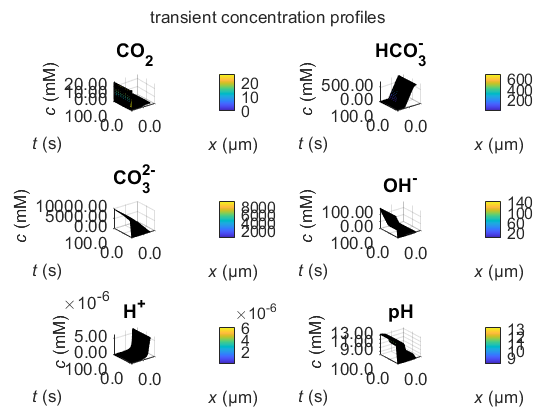

The transients upon imposing -200.0 mA/cm2 at the cathode.


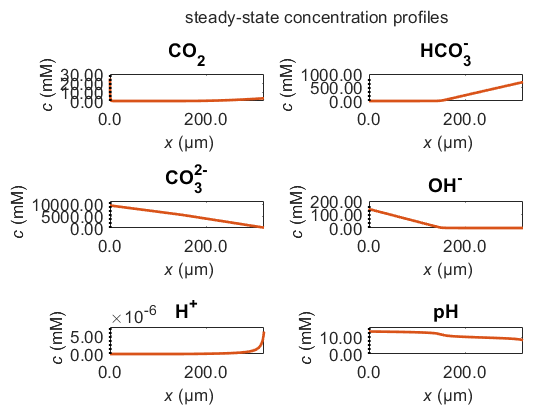

The profiles 100.0 s after imposing -200.0 mA/cm2 at the cathode.


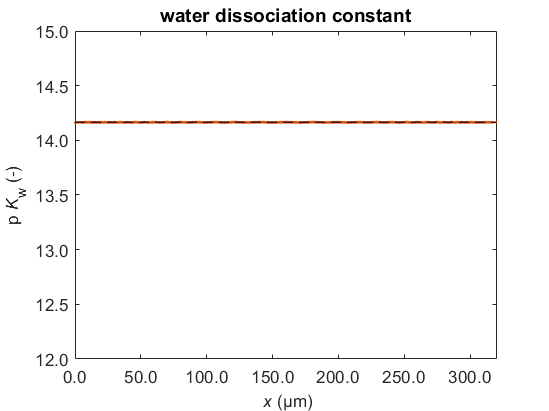

The calculated water dissociation constant compared to the theoretical value (dashed).

Elapsed time for PART IV is 1.179 seconds.


***Total elapsed time for this script is 25.382 seconds.***

 
% make call to model script using above parameters
ptdr_model(T,P,j,n,electrolyte,c,e,l,k_m,L,n_xCL,n_xDBL,t,dt);